# Broken Rotor Fault Detection in AC Induction Motors Using Vibration and Electrical Signals

This example shows how to detect failures in an AC induction motor. Typically, AC motors are driven by a three-phase power converter or an industrial power supply. Failures in the rotor bars of the motor can present themselves in various electrical and vibration signals collected from the system, including voltages and currents of each of the three phases and the acceleration and velocity signals in radial, axial, and tangential directions. Here, you use some of these signals in the **Diagnostic Feature Designer** app to extract features, which you then use to identify the number of broken rotor bars in the motor.

## Data Set

The experimental workbench consists of a three-phase induction motor coupled with a direct-current machine, which works as a generator simulating the load torque, connected by a shaft containing a rotating torque meter. For more details about the workbench setup, see [IEEE Broken Rotor Bar Database](https://ieee-dataport.org/open-access/experimental-database-detecting-and-diagnosing-rotor-broken-bar-three-phase-induction).

The data set contains electrical and mechanical signals from experiments on three-phase induction motors, using the experimental setup shown in the figure.

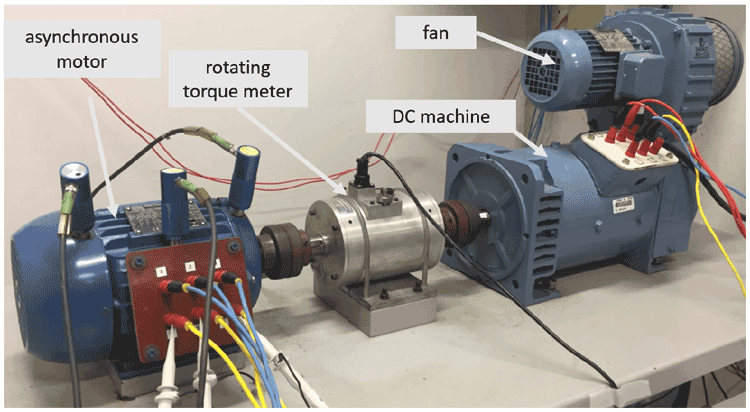

Electrical and vibration signals were collected from the system under the following health and loading conditions:

- 0, 1, 2, 3, and 4 broken rotor bars as the health condition

- 0.5, 1.0, 1.5, 2.0, 2.5, 3.0, 3.5, and 4.0 Nm torque as the load condition

Ten experiments were performed for each combination of health and loading condition. The following signals were acquired during each experiment:

- Voltage of each phase ($V_a$, $V_b$, $V_c$)

- Current draw of each phase ($I_a$, $I_b$, $I_c$)

- Mechanical vibration speeds tangential to the housing (${\textrm{Vib}}_{\;\textrm{carc}}$) and base (${\textrm{Vib}}_{\;\textrm{base}}$)

- Mechanical vibration speed axial on the driven side (${\textrm{Vib}}_{\;\textrm{axial}}$)

- Mechanical vibration speeds radial on the driven side (${\textrm{Vib}}_{\;\textrm{acpi}}$) and nondriven side (${\textrm{Vib}}_{\;\textrm{acpe}}$).

For the full data set, visit [IEEE Broken Rotor Bar Database](https://ieee-dataport.org/open-access/experimental-database-detecting-and-diagnosing-rotor-broken-bar-three-phase-induction), download the entire repository as a ZIP file, and save it in the same directory as this Live Script.

% Remove this comment when using the original data set.
% filename = "banco de dados experimental.zip";

Alternatively, you can use a reduced data set from the [MathWorks repository](https://ssd.mathworks.com/supportfiles/predmaint/broken-rotor-bar-fault-data/experimental_database_short.zip). This data set contains two experiments per operating condition.

% Comment out this section when using the original data set.
filename = "experimental_database_short.zip";
if ~exist(filename,'file')
  url = "https://ssd.mathworks.com/supportfiles/predmaint/broken-rotor-bar-fault-data/" + filename;
  websave(filename,url);
end

Extract the compressed data files into the current folder.

unzip(filename)

## Extract Ensemble Member Data

Convert the original motor data files into individual ensemble member data files for all combinations of health condition, load torque, and experiment index. The files are saved to a target folder and used by the `fileEnsembleDatastore` object in the **Diagnostic Feature Designer** app for data processing and feature extraction.

You can change the amount of experiments per operating condition to use in the ensemble data. If you use the reduced data set, use two experiments; otherwise, you can use up to 10.

numExperiments = 2; % Up to a maximum of 10 if using the original data set

The unzipped files of the original data set are associated with different numbers of broken rotor bars. Create bookkeeping variables to associate the original data files with the corresponding number of broken rotor bars.

% Names of the original data files restored from the zip archive.
files = [ ...
  "struct_rs_R1.mat", ...
  "struct_r1b_R1.mat", ...
  "struct_r2b_R1.mat", ...
  "struct_r3b_R1.mat", ...
  "struct_r4b_R1.mat", ...
  ];

% Rotor conditions (that is, number of broken bars) corresponding to original data files.
health = [
  "healthy", ...
  "broken_bar_1", ...
  "broken_bar_2", ...
  "broken_bar_3", ...
  "broken_bar_4", ...
  ];

Fs_vib = 7600; % Sampling frequency of vibration signals in Hz.
Fs_elec = 50000; % Sampling frequency of electrical signals in Hz.

Create a target folder to store the ensemble member data files that you generate next.

folder = 'data_files';
if ~exist(folder, 'dir')
  mkdir(folder);
end

Iterate over the original data files, where each file corresponds to a given number of broken rotor bars, and construct individual ensemble member data files for each combination of load and number of broken rotor bars.

% Iterate over the number of broken rotor bars.
for i = 1:numel(health)
  fprintf('Processing data file %s\n', files(i))

  % Load the original data set stored as a struct.
  S = load(files(i));
  fields = fieldnames(S);
  dataset = S.(fields{1});

  loadLevels = fieldnames(dataset);
  % Iterate over load (torque) levels in each data set.
  for j = 1:numel(loadLevels)
    experiments = dataset.(loadLevels{j});
    data = struct;

    % Iterate over the given number of experiments for each load level.
    for k = 1:numExperiments
      signalNames = fieldnames(experiments(k));
      % Iterate over the signals in each experimental data set.
      for l = 1:numel(signalNames)
        % Experimental (electrical and vibration) data
        data.(signalNames{l}) = experiments(k).(signalNames{l});
      end

      % Operating conditions
      data.Health = health(i);
      data.Load = string(loadLevels{j});

      % Constant parameters
      data.Fs_vib = Fs_vib;
      data.Fs_elec = Fs_elec;

      % Save memberwise data.
      name = sprintf('rotor%db_%s_experiment%02d',  i-1, loadLevels{j}, k);
      fprintf('\tCreating the member data file %s.mat\n', name)
      filename = fullfile(pwd, folder, name);
      save(filename, '-v7.3', '-struct', 'data'); % Save fields as individual variables.
    end
  end
end

## Construct File Ensemble Datastore

Create a file ensemble datastore for the data stored in the MAT-files, and configure it with functions that interact with the software to read from and write to the datastore.

location = fullfile(pwd, folder);
ens = fileEnsembleDatastore(location,'.mat');

Before you can interact with data in the ensemble, you must create functions that tell the software how to process the data files to read variables into the MATLAB workspace and to write data back to the files. For this example, use the following supplied functions.

- `readMemberData` — Extract requested variables stored in the file. The function returns a table row containing one table variable for each requested variable.  

- `writeMemberData` — Take a structure and write its variables to a data file as individual stored variables. 

ens.ReadFcn = @readMemberData;
ens.WriteToMemberFcn = @writeMemberData;

Finally, set properties of the ensemble to identify data variables, condition variables, and the variables selected to read. These variables include ones that are not in the original data set but rather specified and constructed by `readMemberData`: `Vib_acpi_env`, the band-pass filtered radial vibration signal, and `Ia_env_ps`, the band-pass filtered envelope spectrum of the first-phase current signal. **Diagnostic Feature Designer** can read synthetic signals such as these as well.

ens.DataVariables = [...
  "Va"; "Vb"; "Vc"; "Ia"; "Ib"; "Ic"; ...
  "Vib_acpi"; "Vib_carc"; "Vib_acpe"; "Vib_axial"; "Vib_base"; "Trigger"];
ens.ConditionVariables = ["Health"; "Load"];
ens.SelectedVariables = ["Ia"; "Vib_acpi"; "Health"; "Load"];

% Add synthetic signals and spectra generated directly in the readMemberData
% function.
ens.DataVariables = [ens.DataVariables; "Vib_acpi_env"; "Ia_env_ps"];
ens.SelectedVariables = [ens.SelectedVariables; "Vib_acpi_env"; "Ia_env_ps"];

Examine the ensemble. The functions and the variable names are assigned to the appropriate properties.

ens

Examine a member of the ensemble and confirm that the desired variables are read or generated.

T = read(ens)

From the power spectrum of one of the vibration signals, `Vib_acpi`, observe that there are frequency components of interest in the [900 1300] Hz region. These components are a primary reason why you use `readMemberData` to compute the band-pass filtered variables - `Vib_acpi_env` and `Ia_env_ps`.

% Power spectrum of vibration signal, Vib_acpi
vib = T.Vib_acpi{1};
pspectrum(vib.Data, Fs_vib);
annotation("textarrow", [0.45 0.38], [0.65 0.54], "String", "Fault frequency region of interest")

The envelope of signals after band-pass filtering them can help reveal demodulated signals containing behavior related to the health of the system.

% Envelop of vibration signal
y = bandpass(vib.Data, [900 1300], Fs_vib);
envelope(y)
axis([0 800 -0.5 0.5])

% Specify variables to read
ens.SelectedVariables = ["Vib_acpi_env", "Health"];

% Read all data into a table
T = readall(ens);

% Extract labels
labels = categorical(T.Health);

% Number of observations
numObservations = height(T);

% Initialize cell array for sequences
sequences = cell(numObservations, 1);

% Extract sequences from the vibration signal
for i = 1:numObservations
    % Get the vibration envelope signal data
    signal = T.Vib_acpi_env{i}.Data; % Time-series data
    sequences{i} = signal'; % Transpose to [1 x TimeSteps]
end

% Parameters for feature extraction
windowLength = 512;
overlapLength = 256; % 50% overlap
Fs_vib = 7600; % Vibration sampling frequency

% Define the audioFeatureExtractor object
afe = audioFeatureExtractor( ...
    'SampleRate', Fs_vib, ...
    'Window', hamming(windowLength, 'periodic'), ...
    'OverlapLength', overlapLength, ...
    'spectralCentroid', true, ...
    'spectralFlux', true, ...
    'spectralEntropy', true, ...
    'spectralKurtosis', true, ...
    'spectralSkewness', true, ...
    'spectralRolloffPoint', true);

% Initialize cell array for features
features = cell(numObservations, 1);

% Extract features for each signal
for i = 1:numObservations
    signal = sequences{i}'; % Convert back to column vector
    feats = extract(afe, signal);
    features{i} = feats'; % Transpose to [numFeatures x numTimeSteps]
end


% Determine the number of features
numFeatures = size(features{1}, 1);

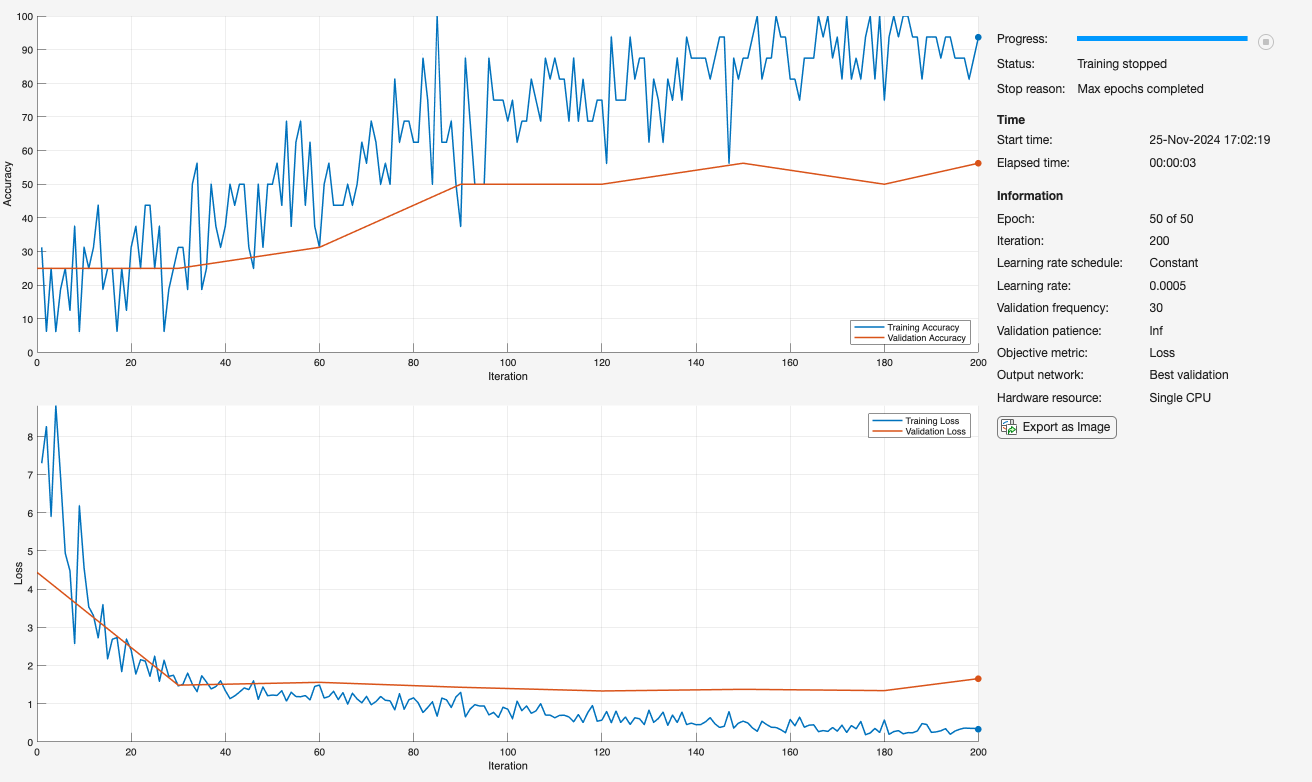

% Reshape features into a 4D format for CNN input: [Height x Width x Channels x Observations]
X = reshape(cat(3, features{:}), size(features{1}, 1), size(features{1}, 2), 1, []);

% Split the dataset into training and validation sets
splitRatio = 0.8;
numTrain = floor(splitRatio * numObservations);

% Shuffle indices
rng(0); % For reproducibility
idx = randperm(numObservations);
trainIdx = idx(1:numTrain);
valIdx = idx(numTrain+1:end);

% Create training and validation sets
XTrain = X(:, :, :, trainIdx);
YTrain = labels(trainIdx);
XValidation = X(:, :, :, valIdx);
YValidation = labels(valIdx);

% Define CNN Architecture
layers = [
    imageInputLayer([size(features{1}, 1), size(features{1}, 2), 1], "Name", "input")

    % First convolutional block
    convolution2dLayer(3, 16, "Padding", "same", "Name", "conv1")
    reluLayer("Name", "relu1")
    maxPooling2dLayer(2, "Stride", 2, "Name", "maxpool1")

    % Second convolutional block
    convolution2dLayer(3, 32, "Padding", "same", "Name", "conv2")
    reluLayer("Name", "relu2")
    maxPooling2dLayer(2, "Stride", 2, "Name", "maxpool2")

    % Third convolutional block
    convolution2dLayer(3, 64, "Padding", "same", "Name", "conv3")
    reluLayer("Name", "relu3")
    maxPooling2dLayer(1, "Stride", 1, "Name", "maxpool3")

    % Fully connected layers
    flattenLayer("Name", "flatten")
    fullyConnectedLayer(128, "Name", "fc1")
    reluLayer("Name", "relu4")
    dropoutLayer(0.6, "Name", "dropout")
    fullyConnectedLayer(numel(categories(YTrain)), "Name", "fc2")
    softmaxLayer("Name", "softmax")
];

% Define training options
opts = trainingOptions("adam", ...
    "InitialLearnRate", 0.0005, ...
    "MaxEpochs", 50, ...
    "MiniBatchSize", 16, ...
    "Shuffle", "every-epoch", ...
    "ValidationData", {XValidation, YValidation}, ...
    "ValidationFrequency", 30, ...
    "Verbose", false, ...
    "Metrics", "accuracy", ...
    "Plots", "training-progress");

% Train the network using trainnet with cross-entropy loss
lossFunction = "crossentropy";
net = trainnet({XTrain, YTrain}, layers, lossFunction, opts);


% Use minibatchpredict to classify validation images and compute accuracy
classNames = categories(YTrain); % Extract class names
scores = minibatchpredict(net, XValidation); % Predict scores
YPred = scores2label(scores, classNames); % Convert scores to predicted labels

% Calculate classification accuracy
accuracy = mean(YPred == YValidation);
disp(['Validation Accuracy: ', num2str(accuracy * 100), '%']);

Validation Accuracy: 50%


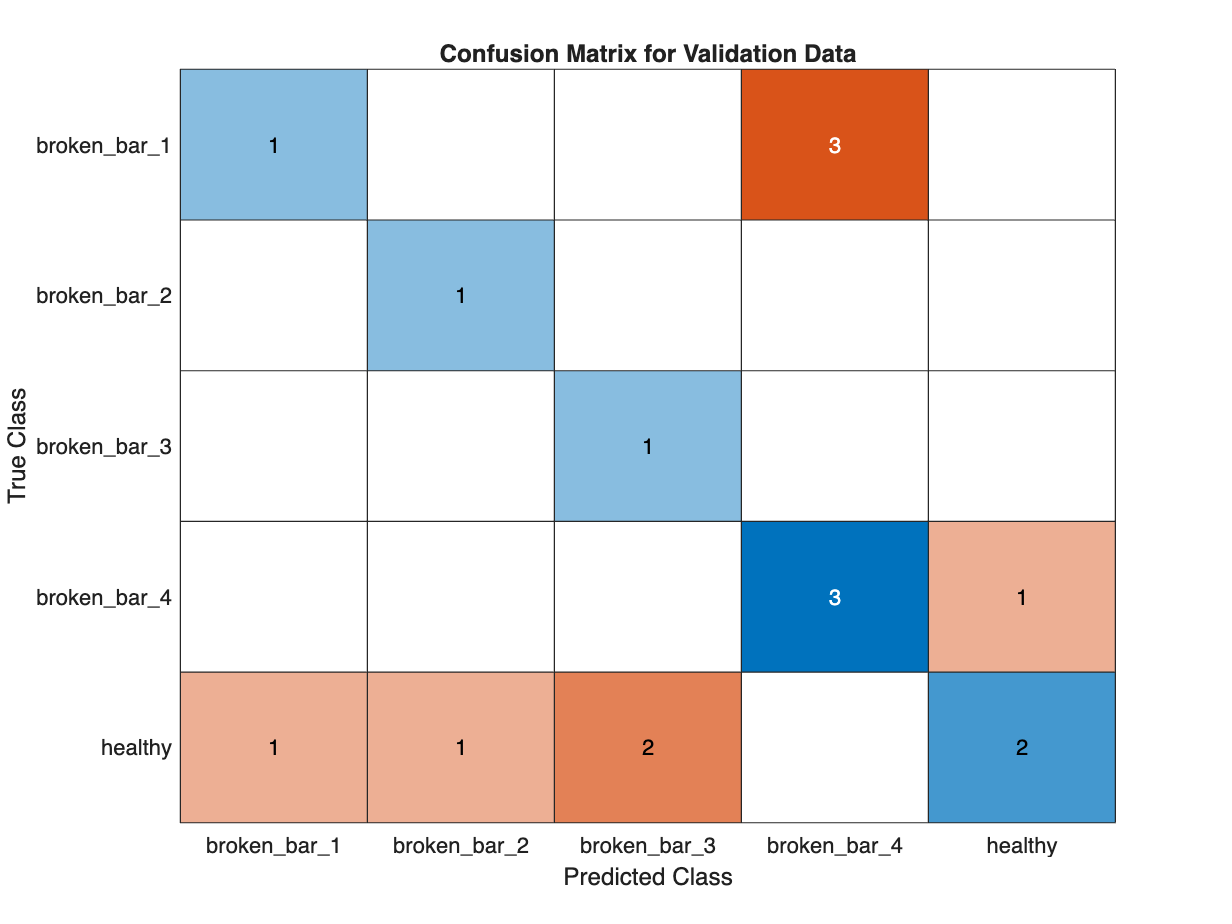


% Plot confusion matrix
figure;
confusionchart(YValidation, YPred);
title('Confusion Matrix for Validation Data');

% Number of classes
numClasses = numel(categories(YTrain));

% Define the LSTM network layers
layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(100, 'OutputMode', 'last') % You can adjust the number of hidden units
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

% Define training options
options = trainingOptions('adam', ...
    'MiniBatchSize', 16, ...
    'MaxEpochs', 50, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {XValidation, YValidation}, ...
    'ValidationFrequency', 30, ...
    'Verbose', false, ...
    'Plots', 'training-progress');

% Train the LSTM network
net = trainNetwork(XTrain, YTrain, layers, options);

% Predict labels for validation data
YPred = classify(net, XValidation, 'MiniBatchSize', 16);

% Calculate accuracy
accuracy = sum(YPred == YValidation) / numel(YValidation);
disp(['Validation Accuracy: ', num2str(accuracy * 100), '%']);

% Plot confusion matrix
figure;
confusionchart(YValidation, YPred);
title('Confusion Matrix for Validation Data');

## Import Data into Diagnostic Feature Designer App

Open the **Diagnostic Feature Designer** app using the following command.

app = diagnosticFeatureDesigner;

You can then import the file ensemble datastore into the app by clicking the **New Session** button and selecting the `ens` variable from the list.

Once preliminary data is read by the app, make sure to uncheck the **Append data to file ensemble** option if you do not want to write new features or data back to the ensemble member files. When you are working with the smaller data set in this example, generating new features directly in memory is faster, so uncheck the option.

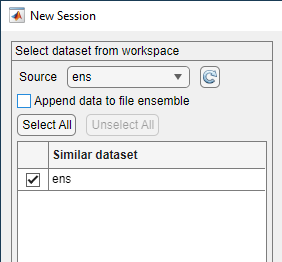

Alternatively, if the whole data set is small enough to fit into your computer's memory, then you can read it into a table object using the following command then import the table into the app directly.

% Working with in-memory data in the app. This may take a couple of minutes to
% run.
T = readall(ens)

### Envelope Signal Data

Select the time-domain signals to import in the tree view of the **New Session** dialog. Here, you only use the synthetic signals, so uncheck `Ia` and `Vib_acpi`. Keep the envelope of the radial vibration speed on the driven side `Vib_acpi_env` checked; you do not need to modify it otherwise.

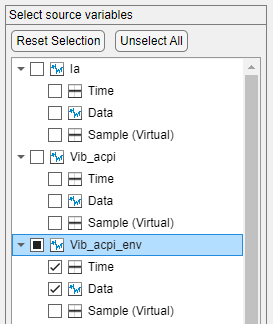

### Envelope Spectrum Data

Select the frequency-domain data to import. Keep the envelope spectrum of Phase A current `Ia_env_ps` selected and change its **Variable type** to `Spectrum`.

Specify `Col1` as an independent (frequency) variable with a corresponding 50 kHz sampling frequency.

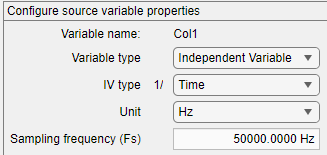

### Condition Variables

Finally, the condition variable of interest for fault classification is the `Health` variable, which corresponds to the number of broken rotor bars in the experiments. Ensure that its **Variable type** is `Condition Variable`.

Confirm the final ensemble specification and click **Import**.

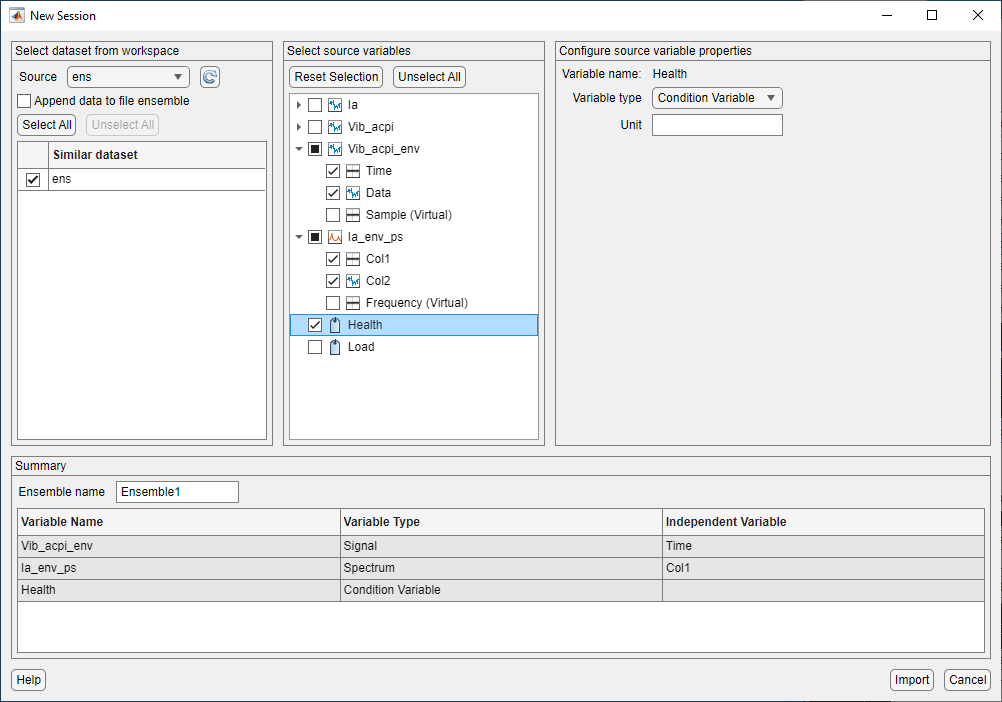

Once the file ensemble is imported, you can visualize the data by creating **Signal Trace** plots and grouping the plot colors based on the **Health** status of the experimental data. Note that reading all members of the file ensemble to produce plots and process the data might be time-consuming depending on the size and number of the data files that need to be read.

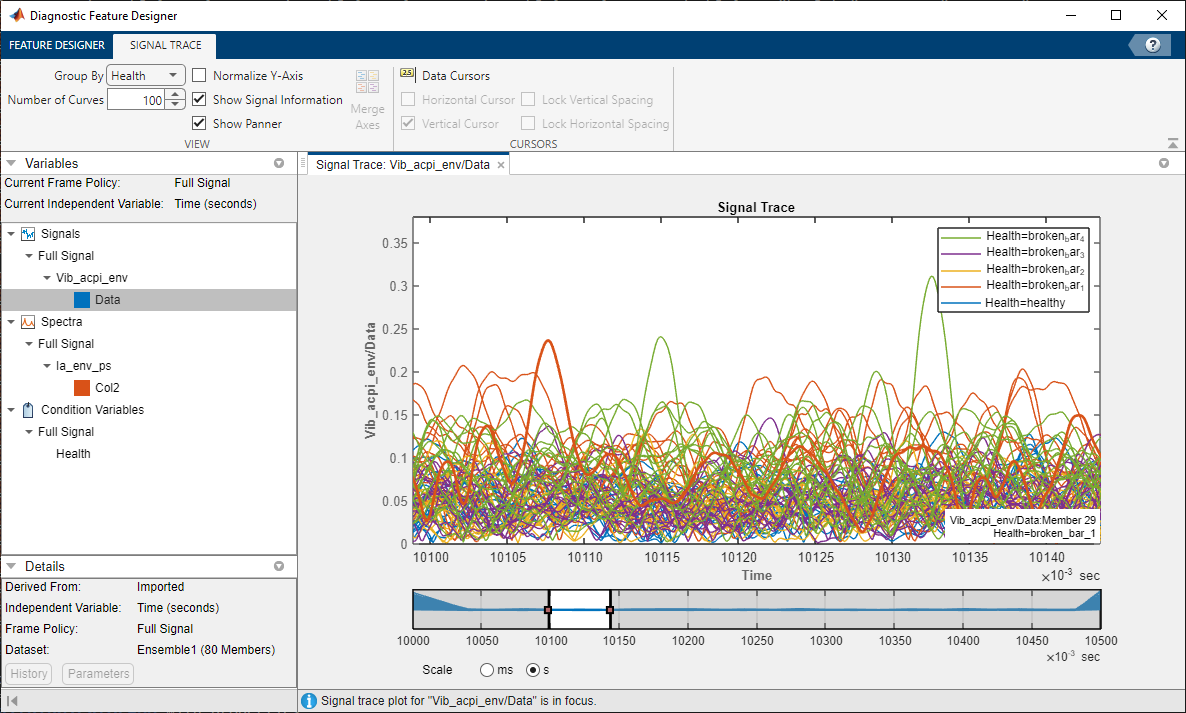

Note that the `getSignal` function used in `readMemberData` reads a portion of the signals from each member file after the initial transients due to motor startup have died down. In this case, the function loads only the data between 10.0 and 11.0 seconds

## Create Predictive Features

The **Auto Features** option is a fast way of creating a large number of features from available signals and ranking them according to their power in separating various health classes. For the imported time-domain signal `Vib_acpi_env`, apply the **Auto Features** option by selecting the signal in the Data Browser tree and clicking **Auto Features** on the **Feature Designer** tab.

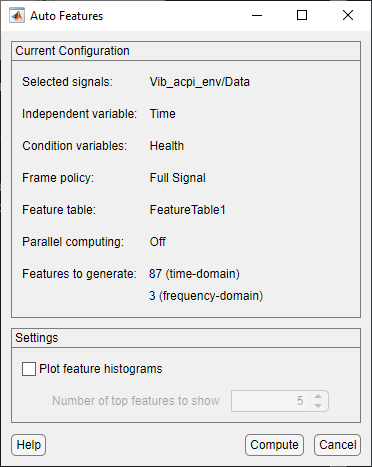

Clicking **Compute** generates a large number of features automatically and ranks them according their importance with respect to the **One-way ANOVA** criterion. This computation might take a few minutes to run.

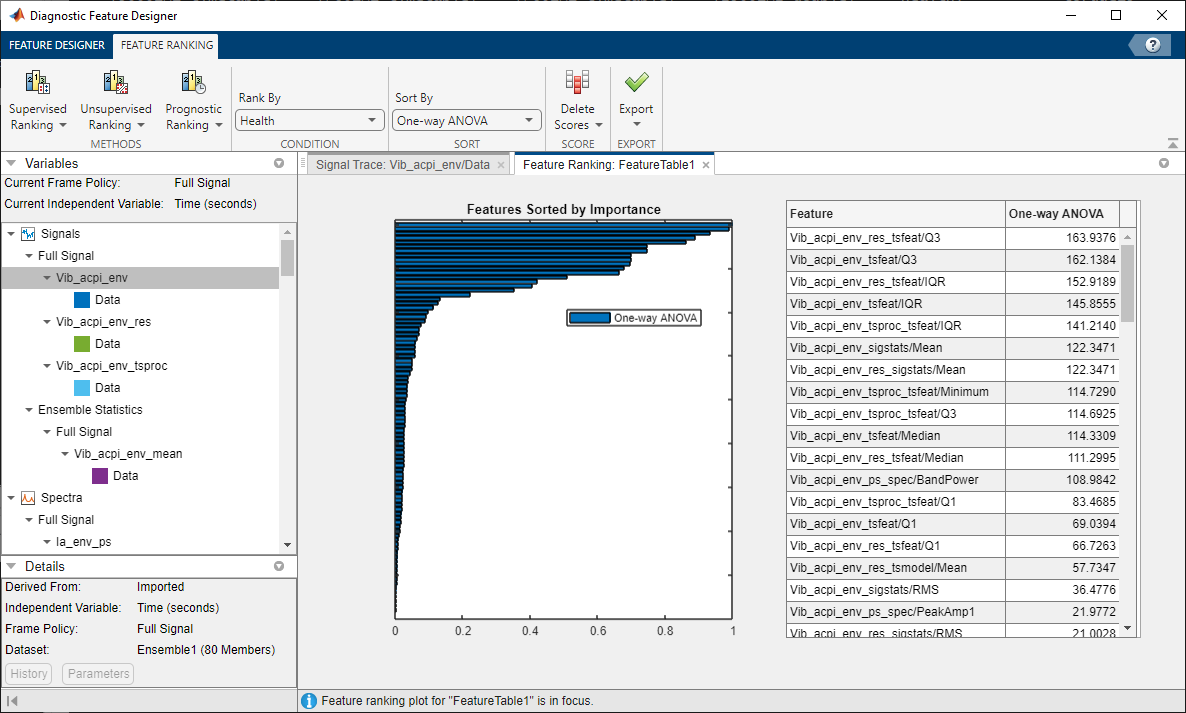

For generating features from envelope spectrum data, a more manual approach can yield more precise results. Select the `Ia_env_ps` signal in the Data Browser, and select **Custom Faults Features** under the **Frequency-Domain Features** menu. Select fault bands around a fundamental frequency of 60 Hz and its first 6 harmonics along with a sideband of 30 Hz to cover most of the spectral peaks in the envelope spectra. Use a fault band width of 10 Hz. Click **Apply** to generate features.

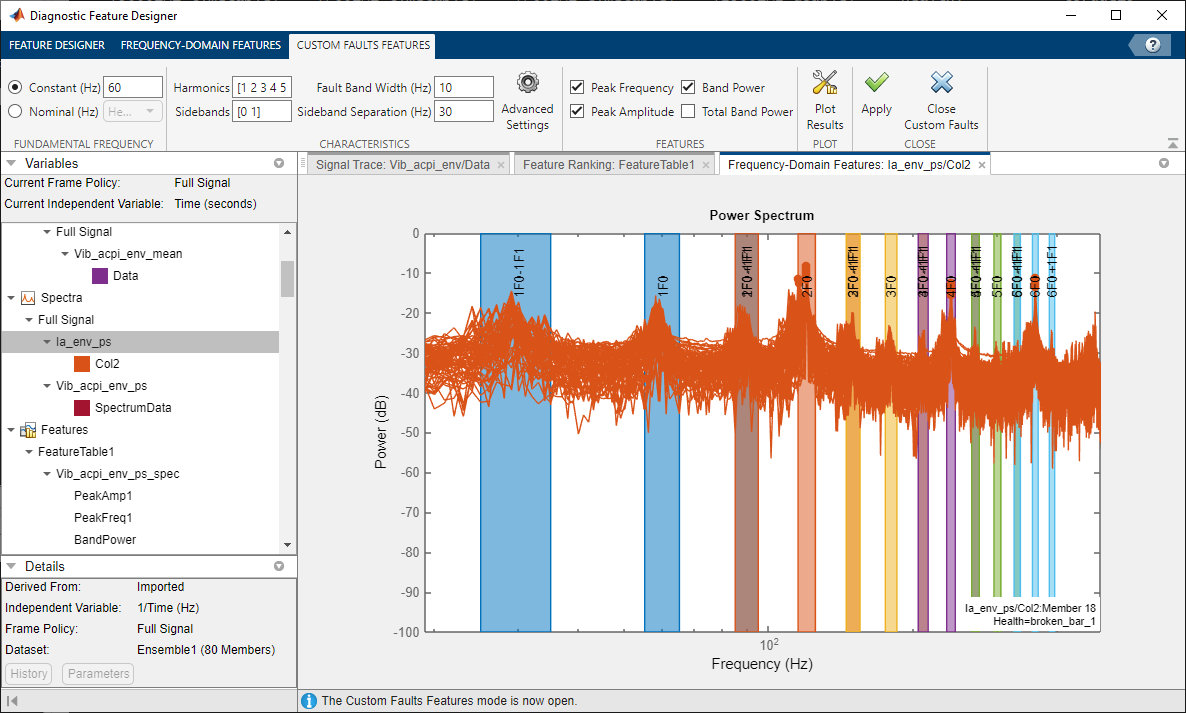

You have now generated a large number of features from the various electrical and vibration signals of the AC motor system.

## Rank Features

This process allows you to quickly create about 150 features both manually and automatically. The final ranking table indicates that the first 10 to 15 features, based on **One-way ANOVA** ranking, help classify the motors according to the number of broken rotor bars in them.

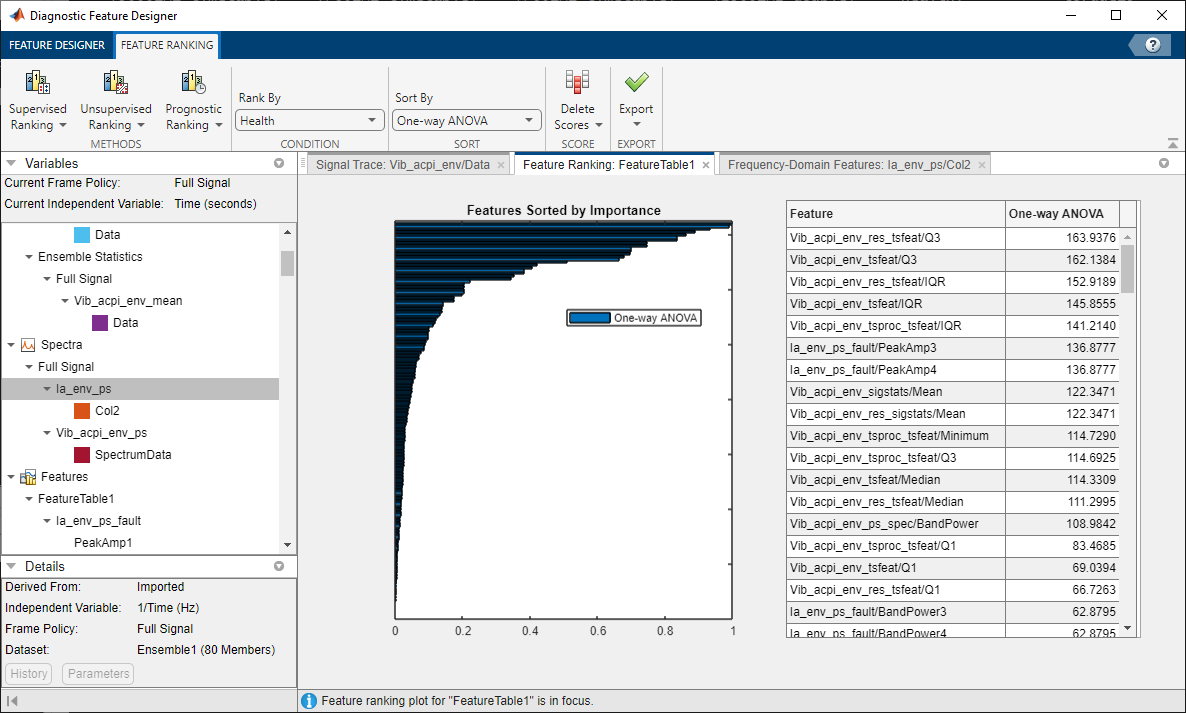

When fault bands and their corresponding names are difficult to identify, use the Peak Frequency feature to identify the corresponding fault band frequency/region.

## Export Features to Classification Learner App and Build a Tree Model

Export the top features from the **Diagnostic Feature Designer** app using **Export >** **Export Features To Classification Learner** on the **Feature Ranking** tab. Change **Select top features** to 10.

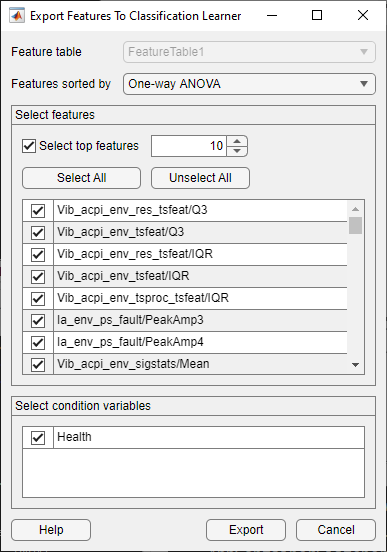

Click **Export** to start the **Classification Learner** app. The **New Session from File** dialog is populated correctly, so click **Start Session** to load the feature data into the app.

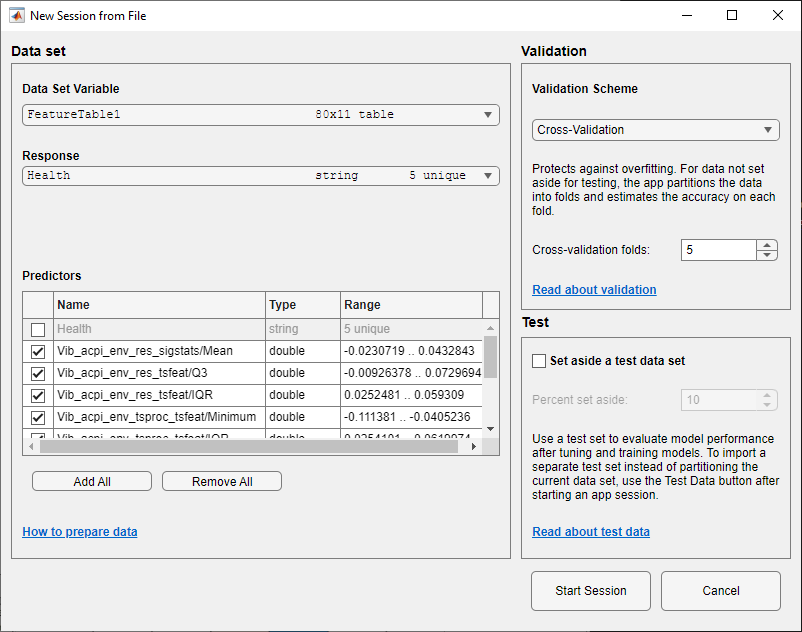

Click **Train All **on the **Classification Learner** tab to obtain a Tree model that achieves about 94% accuracy in classifying the motor faults (that is, the number of broken rotor bars) using the 10 features imported into the app.

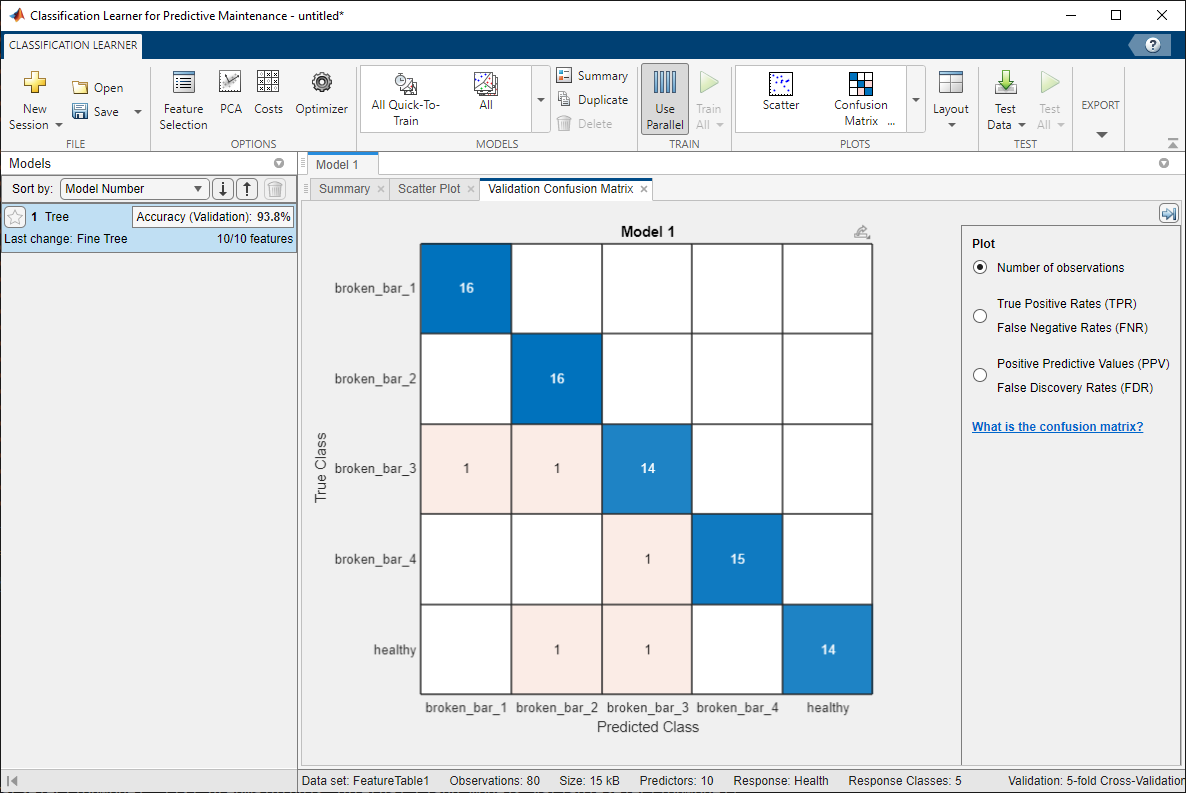

To generate a selection of fast-fitting models, **All Quick-To-Train** from the **Models** gallery, click **Train All**. The weighted KNN model number 2.9 in the figure is able to classify broken rotor faults with about 98% accuracy.

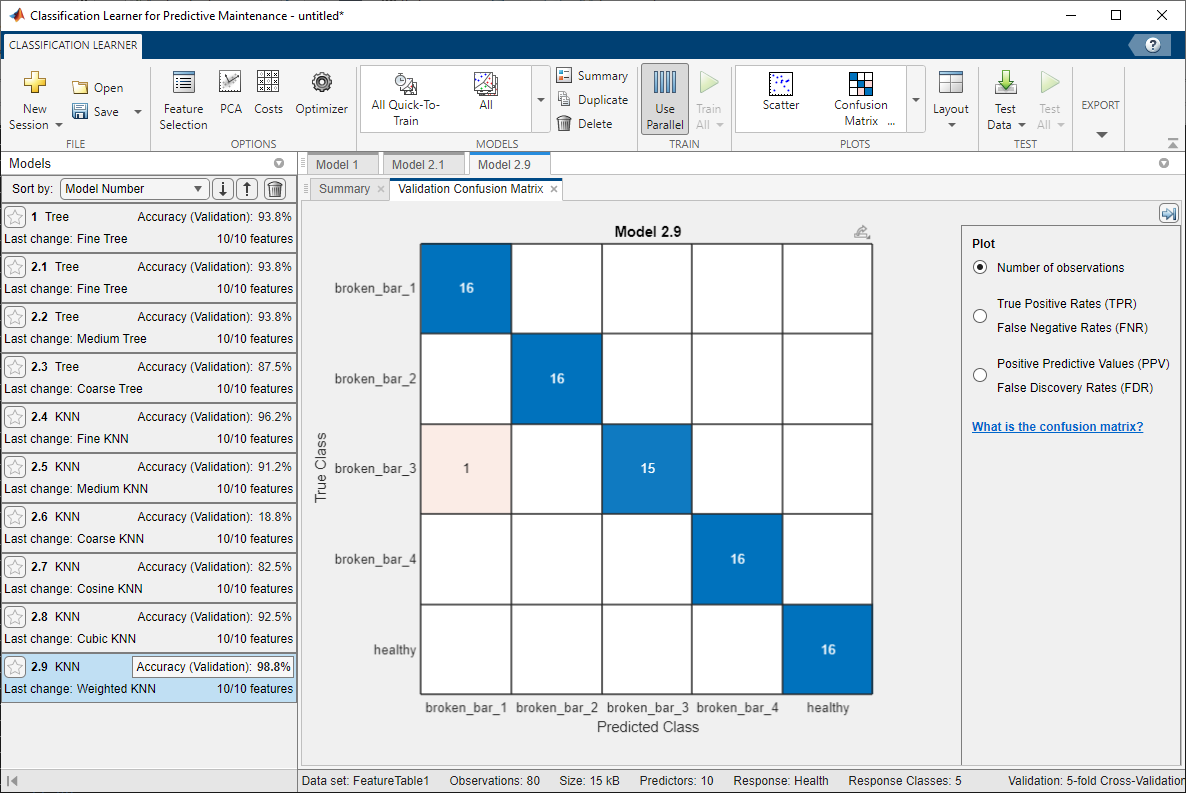

## Supporting Functions

The `WriteToMemberFcn` property of the `fileEnsembleDatastore` object stores the handle of the function responsible for adding new data to each member of the ensemble. The **Diagnostic Feature Designer** app uses this function to save new processed data and extracted features.

function writeMemberData(filename, data)
% Write data into the fileEnsembleDatastore.
%
% Inputs:
%  filename - a string for the file name to write
%  data     - a data structure to write to the file

% Save fields as individual variables.
save(filename, '-append', '-struct', 'data');
end

The function stored in the `ReadFcn` property of the `fileEnsembleDatastore` object reads member data from ensemble member files. The **Diagnostic Feature Designer** app uses this function to read signals, spectra, and features. You can also use this function to create synthetic signals on the fly that can be used in the app.

function T = readMemberData(filename, variables)
% Read variables from a fileEnsembleDatastore
%
% Inputs:
%  filename  - file to read, specified as a string
%  variables - variable names to read, specified as a string array
%              Variables must be a subset of SelectedVariables specified in
%              the fileEnsembleDatastore.
% Output:
%  T         - a table with a single row

mfile = matfile(filename); % Allows partial loading

% Read condition variables directly from the top-level structure fields
T = table();
for i = 1:numel(variables)
  var = variables(i);

  switch var
    case {'Health', 'Load'}
      % Condition variables
      val = mfile.(var);
    case {'Va', 'Vb', 'Vc', 'Ia', 'Ib', 'Ic'}
      % Electrical signals
      val = getSignal(mfile, var, mfile.Fs_elec);
    case {'Vib_acpi', 'Vib_carc', 'Vib_acpe', 'Vib_axial', 'Vib_base', 'Trigger'}
      % Vibration signals
      val = getSignal(mfile, var, mfile.Fs_vib);
    case {'Vib_acpi_env'}
      % Synthetic envelope signals for vibration data
      sig = regexprep(var, '_env', '');
      TT = getSignal(mfile, sig, mfile.Fs_vib);
      % Envelope of band-pass filtered signal
      y = bandpass(TT.Data, [900 1300], mfile.Fs_vib);
      yUpper = envelope(y);
      val = timetable(yUpper, 'VariableNames', "Data", 'RowTimes', TT.Time);
    case {'Ia_env'}
      % Synthetic envelope signals for electrical data
      sig = regexprep(var, '_env', '');
      TT = getSignal(mfile, sig, mfile.Fs_elec);
      % Envelope of band-pass filtered signal
      y = bandpass(TT.Data, [900 1300], mfile.Fs_elec);
      yUpper = envelope(y);
      val = timetable(yUpper, 'VariableNames', "Data", 'RowTimes', TT.Time);
    case {'Ia_env_ps'}
      % Synthetic envelope spectra for electrical data
      sig = regexprep(var, '_env_ps', '');
      TT = getSignal(mfile, sig, mfile.Fs_elec);
      % Envelope spectrum of band-pass filtered signal
      [ES,F] = envspectrum(TT, 'Method', 'hilbert', 'Band', [900 1300]);
      val = [F,ES];
    otherwise
      % Other features and signals.
      val = mfile.(var);
  end

  if numel(val) > 1
    val = {val};
  end

  % Add the data to the output table, using the variable name.
  T.(var) = val;
end
end

When the original signal is longer than what is needed to extract useful features from it, you can use the following helper function to extract a shorter portion of the full signal from the member data.

function TT = getSignal(mfile, signame, Fs)
% Extract a 1.0 second portion of the signal after 10 seconds of measurements.
signame = char(signame);
n = size(mfile, signame, 1);
t = (0:n-1)' / Fs;
I = find((t >= 10.0) & (t <= 11.0)); % 1.0 sec of data
TT = timetable(mfile.(signame)(I,1), 'VariableNames', "Data", 'RowTimes', seconds(t(I)));
end

## References

- Treml, Aline Elly, Rogério Andrade Flauzino, Marcelo Suetake, and Narco Afonso Ravazzoli Maciejewski. "Experimental database for detecting and diagnosing rotor broken bar in a threephase induction motor." IEEE Dataport, updated September 24, 2020, [https://dx.doi.org/10.21227/fmnm-bn95](https://dx.doi.org/10.21227/fmnm-bn95).

*Copyright 2022-2023 The MathWorks, Inc.*